
clear
close all
clc

%% Data & Initialization

%Definition of the LTI system
LTI.A=[0 0; 1 0]; 
LTI.B=[1; 0];
LTI.x0=[3;3];

%Definition of system dimension
dim.nx=2;     %state dimension
dim.nu=1;     %input dimension
dim.N=2;      %horizon

%Definition of quadratic cost function
weight.Q=[1 2; 2 6];   %weight on output
weight.R=0;            %weight on input

T_sim=20;                  %simulation horizon

## Generate prediction model

Recall (see Exercise set 2, ex. 5):


$$\mathbf{x}_{N+1}=Tx_0+S\mathbf u_N$$


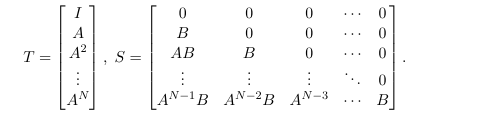



% Generation of prediction model 
%Prediction matrix from initial state
T=zeros(dim.nx*(dim.N+1),dim.nx);
for k=0:dim.N
    T(k*dim.nx+1:(k+1)*dim.nx,:)=LTI.A^k;
end

%Prediction matrix from input
S=zeros(dim.nx*(dim.N+1),dim.nu*(dim.N));
for k=1:dim.N
    for i=0:k-1
        S(k*dim.nx+1:(k+1)*dim.nx,i*dim.nu+1:(i+1)*dim.nu)=LTI.A^(k-1-i)*LTI.B;
    end
end

predmod.T=T;
predmod.S=S;

## Generate cost 

In this case, M = 0 (no cross-product term between input and state)

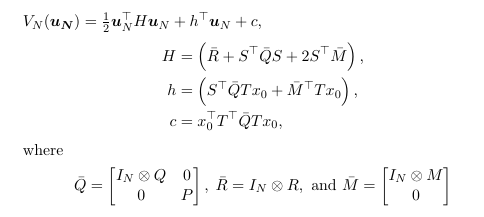

Qbar=blkdiag(kron(eye(dim.N),weight.Q),zeros(dim.nx)); 
H=predmod.S'*Qbar*predmod.S+kron(eye(dim.N),weight.R);   
h=predmod.S'*Qbar*predmod.T;

### Simulate unconstrained system with short horizon:

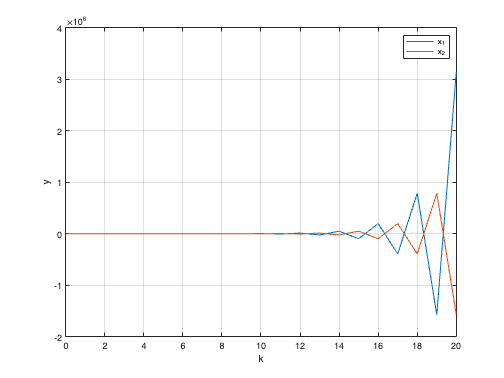

x=zeros(dim.nx,T_sim+1);
u_rec=zeros(dim.nu,T_sim);
x(:,1)=LTI.x0;
% Receding horizon implementation
for k=1:T_sim
    x_0=x(:,k); 
    % Solve the unconstrained optimization problem (with YALMIP)
    u_uncon = sdpvar(dim.nu*dim.N,1);                        %define optimization variable
    Constraint=[];                                           %define constraints
    Objective = 0.5*u_uncon'*H*u_uncon+(h*x_0)'*u_uncon;     %define cost function
    ops =  sdpsettings('verbose',0);
    optimize(Constraint,Objective, ops);                     %solve the problem
    u_uncon=value(u_uncon);                                  %assign the solution
    
    % Select the first input only
    u_rec(k)=u_uncon(1);

    % Compute the state/output evolution
    x(:,k+1)=LTI.A*x_0 + LTI.B*u_rec(k);
    clear u_uncon
    
end

% Plots
figure,
plot(0:T_sim, x),
xlabel('k'), ylabel('y'), grid on;
legend('x_1','x_2');

### Simulate system with short horizon and terminal constraint:


$$x(N) = A^Nx_0 + A^{N-1}Bu(0) + A^{N-2}Bu(1) + ... + AB u(N-2) + B u(N-1) 
$$



$$x(N) = A^Nx_0 + [A^{N-1}B+ A^{N-2}B + ... + AB + B] \mathbf{u}_N$$



$$A_e\mathbf u_N + b_e = 0 \Leftarrow A_e =  [A^{N-1}B, ... ,AB, B];  b_e = A^Nx_0
$$


Note: the latter terms are the bottom rows of the matrices T and S

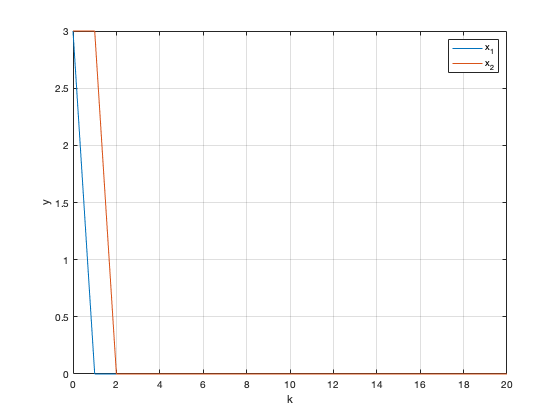

constraints.Ae=predmod.S(end-dim.nx+1:end,:);
constraints.be=predmod.T(end-dim.nx+1:end,:);

x=zeros(dim.nx,T_sim+1);
u_rec=zeros(dim.nu,T_sim);
x(:,1)=LTI.x0;

for k=1:T_sim
    x_0=x(:,k);  
    % Solve the constrained optimization problem (with YALMIP)
    u_con = sdpvar(dim.nu*dim.N,1);                             %define optimization variable
    Constraint=[constraints.Ae*u_con==-constraints.be*x_0];     %define constraints
    Objective = 0.5*u_con'*H*u_con+(h*x_0)'*u_con;              %define cost function
    optimize(Constraint,Objective,ops);                         %solve the problem
    u_con=value(u_con);                                         %assign the solution
    
    % Select the first input only
    u_rec(k)=u_con(1);

    % Compute the state/output evolution
    x(:,k+1)=LTI.A*x_0 + LTI.B*u_rec(k);
    clear u_uncon
end


% Plots
figure,
plot(0:T_sim, x),
xlabel('k'), ylabel('y'), grid on;
legend('x_1','x_2');

### Simulate system with long horizon

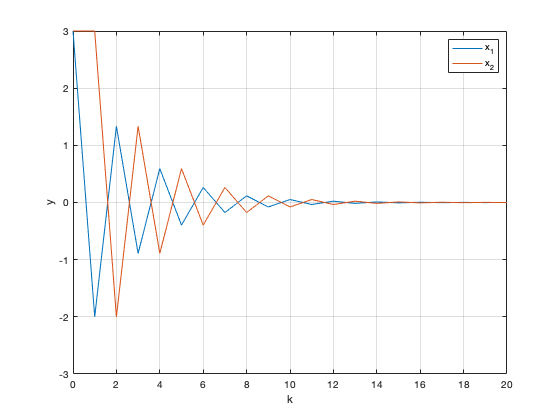

dim.N=3;
predmod=predmodgen(LTI,dim);            
[H,h]=costgen(predmod,weight,dim);


% Receding horizon implementation
x=zeros(dim.nx,T_sim+1);
u_rec=zeros(dim.nu,T_sim);
x(:,1)=LTI.x0;
constraints=constraintgen(predmod,dim);


for k=1:T_sim
    
    x_0=x(:,k);
    
    % Solve the unconstrained optimization problem (with YALMIP)
    u_uncon = sdpvar(dim.nu*dim.N,1);                        %define optimization variable
    Constraint=[];                             %define constraints
    Objective = 0.5*u_uncon'*H*u_uncon+(h*x_0)'*u_uncon;     %define cost function
    optimize(Constraint,Objective, ops);                          %solve the problem
    u_uncon=value(u_uncon);                                  %assign the solution
    
    % Select the first input only
    u_rec(k)=u_uncon(1);

    % Compute the state/output evolution
    x(:,k+1)=LTI.A*x_0 + LTI.B*u_rec(k);
    clear u_uncon
    
end

% Plots
figure,
plot(0:T_sim, x),
xlabel('k'), ylabel('y'), grid on;
legend('x_1','x_2');